%% Parameterize the arm
rho = 0.03; % M, Radius
 
% Construct pose matrices
% Transform from world frame to base curve
g_o = SE2(0, 0, pi/2);

g_o_A = SE2(0, rho/2, 0);
g_o_B = SE2(0, -rho/2, 0);

l_0 = 0.1; % Default length

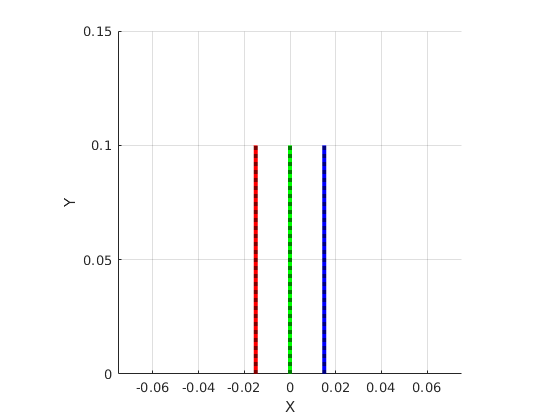

% Create arm object and initialize plotting
planar_arm_obj = Arm2D(g_o, {g_o*g_o_A; g_o; g_o*g_o_B}, l_0, 'plot_unstrained', true);

fig = figure();
line_options_muscles = struct("LineWidth", 3);

% Initialize plotting
planar_arm_obj.initialize_plotting(axes(fig), "line_options_muscles", line_options_muscles);

border_length_cm = 15;
ylim(planar_arm_obj.ax, [0, 1] * border_length_cm / 100);
xlim(planar_arm_obj.ax, [-0.5, 0.5] * border_length_cm / 100);

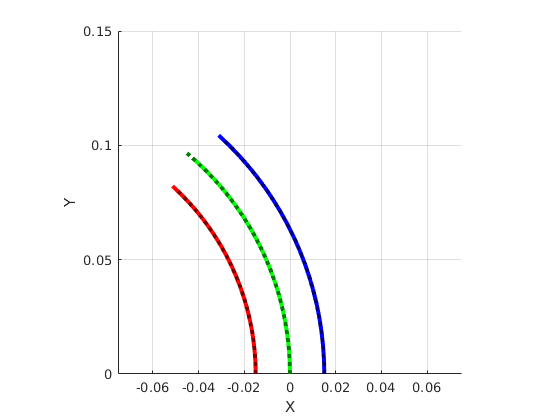

l_A = 0.09;
l_B = 0.11;
l_C = 0.115;
v_l = [l_A; l_B; l_C];
planar_arm_obj.plot_unstrained = true;
planar_arm_obj.update_arm(v_l);